% Experiental DSP Exercise 2

[x, F] = audioread("audio.wav");
x = x(:,1);  % use one channel if stereo

% Time axis
duration = length(x)/F

duration = 0.0320

t = (0:length(x)-1)/F;

% Plot waveform
figure;
plot(t, x);
xlabel('Time (s)'); ylabel('Amplitude');
title('Audio waveform');

% Find peaks with conditions
[~, peak_indices] = findpeaks(x, ...
    'MinPeakProminence', 0.1, ...          % adjust threshold
    'MinPeakDistance', round(F*0.001));    % 1 ms apart minimum

% Estimate period from multiple peaks
diffs = diff(peak_indices);       % spacing between peaks (samples)
period_in_samples = median(diffs);
approx_period = period_in_samples / F;

disp(['Approximate period = ', num2str(approx_period), ' seconds']);

Approximate period = 0.004125 seconds


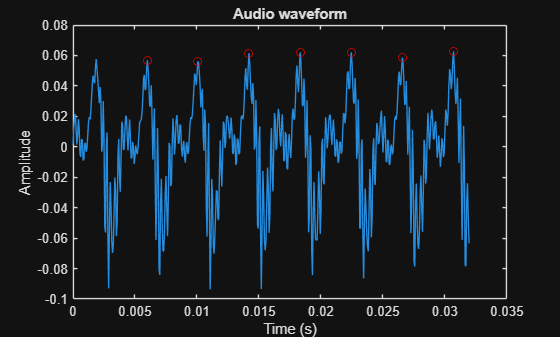


% Visual check: overlay peaks
hold on;
plot(t(peak_indices), x(peak_indices), 'ro');

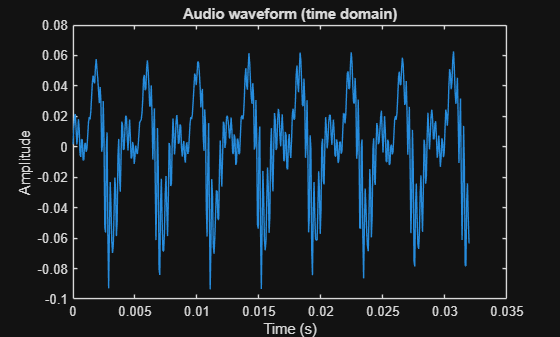

% Part B
% Read audio
[x, Fs] = audioread("audio.wav");
x = x(:,1);                 % use single channel if stereo
N = length(x);

% Part A plot (optional): time domain
t = (0:N-1)/Fs;
figure;
plot(t, x);
xlabel('Time (s)'); ylabel('Amplitude');
title('Audio waveform (time domain)');

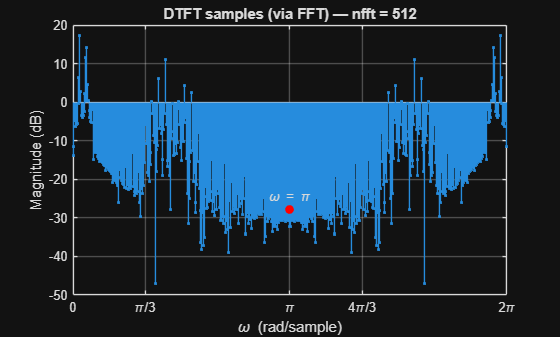


% Part B: FFTs
nfft1 = 512;
nfft2 = 1024;

X1 = fft(x, nfft1);   % returns bins 0..nfft1-1 corresponding to omega 0..2pi*(nfft1-1)/nfft1
X2 = fft(x, nfft2);

% Frequency axes (radians/sample) for 0..2pi
w1 = (0:nfft1-1) * (2*pi / nfft1);   % length nfft1
w2 = (0:nfft2-1) * (2*pi / nfft2);   % length nfft2

% Magnitude in dB (safe flooring to avoid log(0))
magX1dB = 20*log10(max(abs(X1), eps));
magX2dB = 20*log10(max(abs(X2), eps));

% Plot 1: nfft = 512
figure;
stem(w1, magX1dB, '.');
xlabel('\omega (rad/sample)');
ylabel('Magnitude (dB)');
title(['DTFT samples (via FFT) — nfft = ', num2str(nfft1)]);
xlim([0 2*pi]);
xticks([0 pi/3 pi 4*pi/3 2*pi]);
xticklabels({'0','\pi/3','\pi','4\pi/3','2\pi'});
grid on;
hold on;
% mark mid point at omega = pi
idx_mid1 = nfft1/2 + 1;                   % when nfft1 is even; MATLAB indexing
plot(w1(idx_mid1), magX1dB(idx_mid1), 'ro', 'MarkerFaceColor','r');
text(w1(idx_mid1), magX1dB(idx_mid1)+3, '\omega = \pi', 'HorizontalAlignment','center');


% Plot 2: nfft = 1024
figure;
stem(w2, magX2dB, '.');
xlabel('\omega (rad/sample)');
ylabel('Magnitude (dB)');
title(['DTFT samples (via FFT) — nfft = ', num2str(nfft2)]);
xlim([0 2*pi]);
xticks([0 pi/3 pi 4*pi/3 2*pi]);
xticklabels({'0','\pi/3','\pi','4\pi/3','2\pi'});
grid on;
hold on;
idx_mid2 = nfft2/2 + 1;
plot(w2(idx_mid2), magX2dB(idx_mid2), 'ro', 'MarkerFaceColor','r');
text(w2(idx_mid2), magX2dB(idx_mid2)+3, '\omega = \pi', 'HorizontalAlignment','center');

% Demonstrate index mapping (example for a few indices)
% index k in X1 corresponds to index round(k * (nfft2/nfft1)) in X2
scale = nfft2 / nfft1;
k_examples = [1, 10, 50, idx_mid1, 511];          % example indices in X1 (1-based)
mapped = round(k_examples * scale);
disp('Example mapping from X1 indices -> X2 indices:');

Example mapping from X1 indices -> X2 indices:


disp(table(k_examples.', mapped.', 'VariableNames', {'k_in_X1','mapped_k_in_X2'}));

    k_in_X1    mapped_k_in_X2
    _______    ______________

        1              2     
       10             20     
       50            100     
      257            514     
      511           1022     



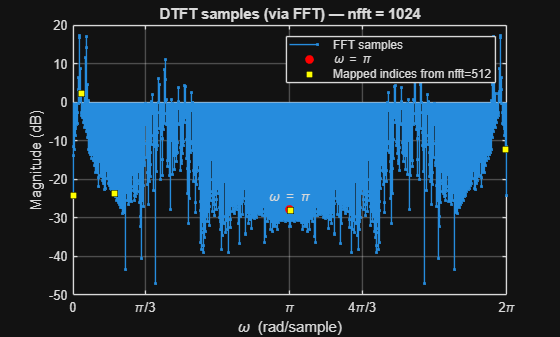


% visually compare: plot markers on figure 2 for the mapped bins
figure(gcf); % ensure figure2 is current
hold on;
plot(w2(mapped), magX2dB(mapped), 'ks', 'MarkerFaceColor','y');
legend('FFT samples','\omega = \pi','Mapped indices from nfft=512');